# This code is for filtering the data with random trigger and plotting the 2D Ion TOF-TOF spectra


%% import the data if already converted to ANA
dir= 'E:\PhD\Adamantane_data\data\Ada_PEPICO_hv350eV_ke260_0003\Ada_PEPICO_hv350eV_ke260_0003_ana';
raw_data = IO.import_raw(dir);
addpath(genpath('E:\PhD\Adamantane_data\mdata'))
mdata = md_all();
data            = macro.filter(raw_data, mdata); %define the multiplicity of events
data_corrected = macro.correct(data, mdata);

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


data_converted = macro.convert(data_corrected, mdata);

Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
Log: Background signal created for det2 on the signal(s) TOF,


## Event statistics from all data

[data_stats] =get_data_stats(data_converted);

The Scaling factor is 0.3974


SC = data_stats.SC;
TP_0 =data_stats.TP_0;

## Create TOF distribution

Binsize = 10; Binedges = 2000: Binsize: 11e3;
Bincenters = Binedges(1:end-1) + diff(Binedges) / 2; %tof values

## Define etII(tof1, tof2)

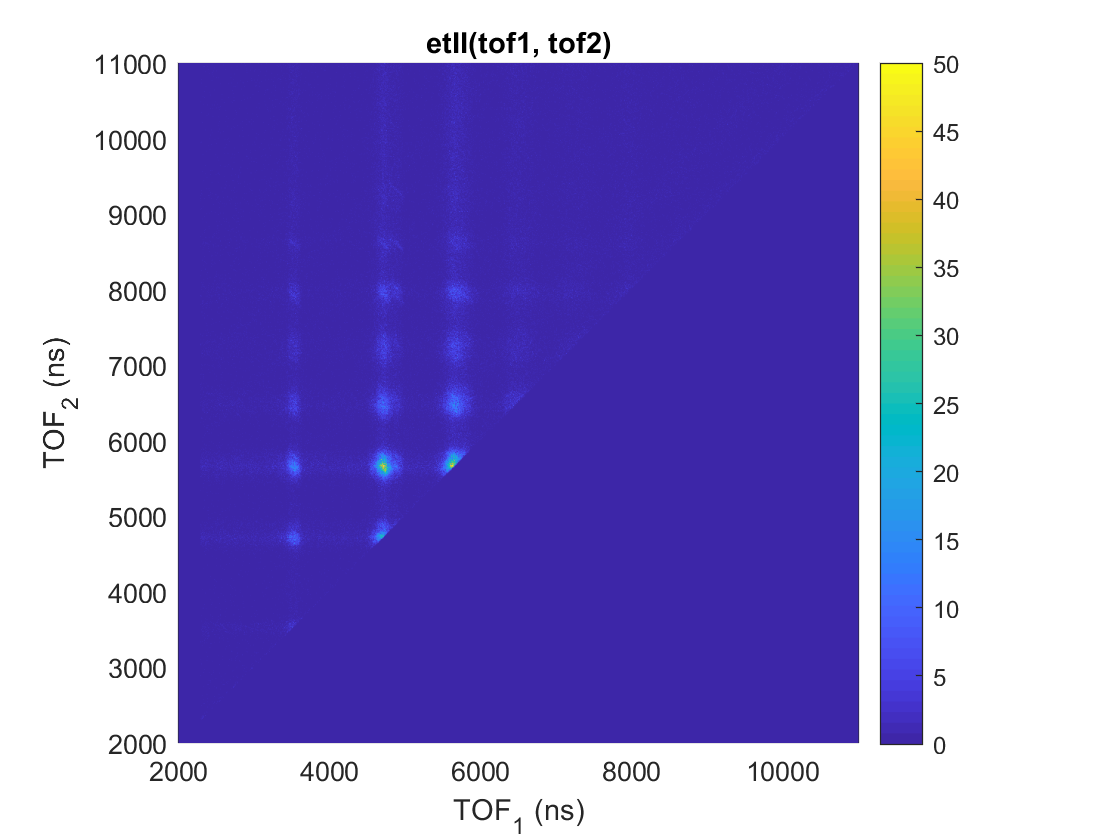

etN.e_TRG= macro.filter.write_coincidence_condition(1, 'det1'); %electron trigger
etN.ions= macro.filter.write_coincidence_condition(2, 'det2');
[e_filter_etN, ~]	= macro.filter.conditions_2_filter(data_converted,etN);

hit_filter_et_c2 = filter.events_2_hits(e_filter_etN, data_converted.e.raw, [2, length(data_converted.h.det2.TOF)],...
    etN, data_converted);

et_tof_c2= data_converted.h.det2.TOF(hit_filter_et_c2.det2.filt); 

%%% the odd index values of et_tof_c2 are tof1%%%
% odd index values
et_c2_tof1 = et_tof_c2(1:2:end) ;
%%% the even index values of et_tof_c2 are tof2%%%
% even index values
et_c2_tof2 = et_tof_c2(2:2:end) ;


[et_tof2,~,~] = histcounts2(et_c2_tof1,et_c2_tof2,Binedges,Binedges);
figure
histogram2('XBinEdges',Binedges,'YBinEdges',Binedges,'BinCounts',et_tof2,'DisplayStyle','tile','ShowEmptyBins','on')
colorbar
title('etII(tof1, tof2)')
xlabel('TOF_1 (ns)')
ylabel('TOF_2 (ns)')
axis equal

% caxis([0 10])
% xlim([4006 9670])
% ylim([4888 10553])

## Projections : Ion TOF for C2 

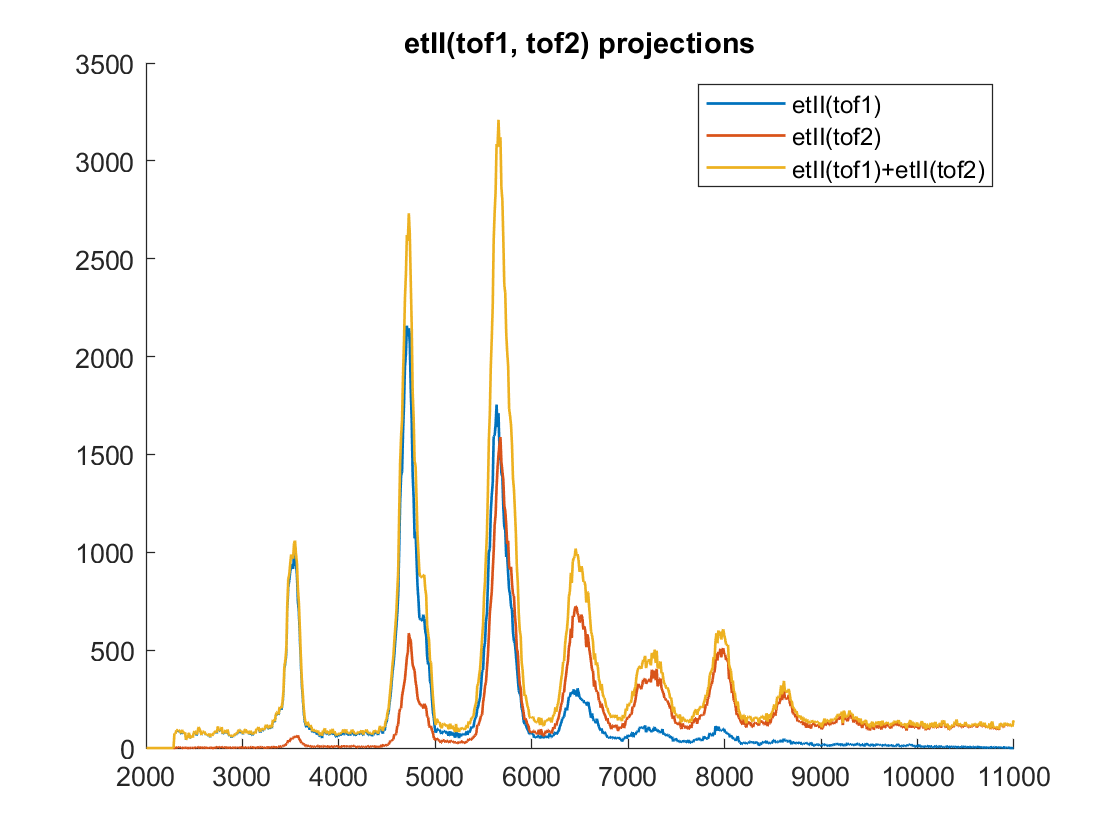

tof1_hist = sum(et_tof2,2);
tof2_hist = sum(et_tof2,1);

figure
hold on
plot(Bincenters, tof1_hist,'LineWidth',1,'DisplayName','etII(tof1)');
plot(Bincenters, tof2_hist,'LineWidth',1,'DisplayName','etII(tof2)');
title('etII(tof1, tof2) projections')
legend

proj_et_tof2 = tof1_hist +tof2_hist';

plot(Bincenters, proj_et_tof2,'LineWidth',1,'DisplayName','etII(tof1)+etII(tof2)');

## Define rtII(tof1, tof2)

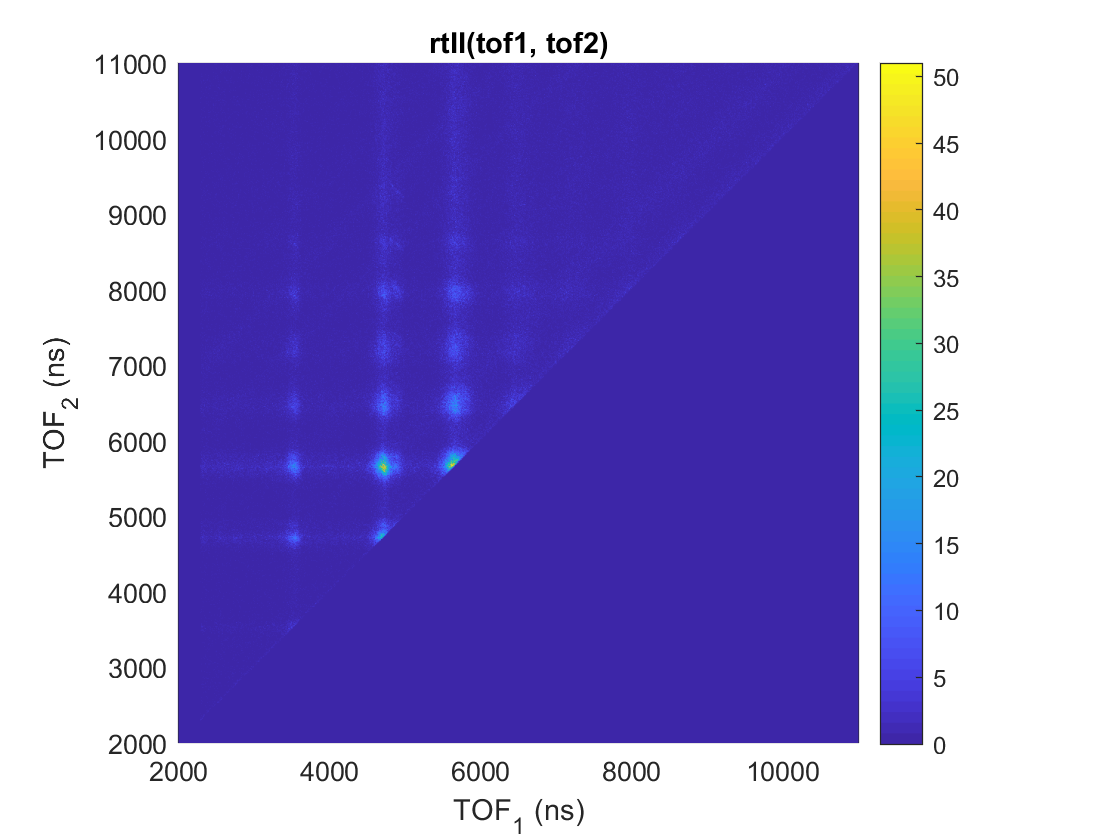

rtN.e_TRG= macro.filter.write_coincidence_condition(0, 'det1'); %rnd trigger
rtN.ions= macro.filter.write_coincidence_condition(2, 'det2');
[e_filter_rtN, ~]	= macro.filter.conditions_2_filter(data_converted,rtN);

hit_filter_rt_c2 = filter.events_2_hits(e_filter_rtN, data_converted.e.raw, [2, length(data_converted.h.det2.TOF)],...
    rtN, data_converted);

rt_tof_c2= data_converted.h.det2.TOF(hit_filter_rt_c2.det2.filt); 

%%% the odd index values of et_tof_c2 are tof1%%%
% odd index values
rt_c2_tof1 = rt_tof_c2(1:2:end) ;
%%% the even index values of et_tof_c2 are tof2%%%
% even index values
rt_c2_tof2 = rt_tof_c2(2:2:end) ;


[rt_tof2,~,~] = histcounts2(rt_c2_tof1,rt_c2_tof2,Binedges,Binedges);
figure
histogram2('XBinEdges',Binedges,'YBinEdges',Binedges,'BinCounts',rt_tof2,'DisplayStyle','tile','ShowEmptyBins','on')
colorbar
title('rtII(tof1, tof2)')
xlabel('TOF_1 (ns)')
ylabel('TOF_2 (ns)')
axis equal

## Define etI(tof)

etN.e_TRG= macro.filter.write_coincidence_condition(1, 'det1'); %electron trigger
etN.ions= macro.filter.write_coincidence_condition(1, 'det2');
[e_filter_etN, ~]	= macro.filter.conditions_2_filter(data_converted,etN);

hit_filter_et_c1 = filter.events_2_hits(e_filter_etN, data_converted.e.raw, [2, length(data_converted.h.det2.TOF)],...
    etN, data_converted);

et_tof_c1= data_converted.h.det2.TOF(hit_filter_et_c1.det2.filt);

et_tof1= histcounts(et_tof_c1, Binedges);%,'Normalization','probability');


## Define rtI(tof)

rtN.e_TRG= macro.filter.write_coincidence_condition(0, 'det1'); %rnd trigger
rtN.ions= macro.filter.write_coincidence_condition(1, 'det2');
[e_filter_rtN, ~]	= macro.filter.conditions_2_filter(data_converted,rtN);

hit_filter_rt_c1 = filter.events_2_hits(e_filter_rtN, data_converted.e.raw, [2, length(data_converted.h.det2.TOF)],...
    rtN, data_converted);

rt_tof_c1= data_converted.h.det2.TOF(hit_filter_rt_c1.det2.filt);

rt_tof1= histcounts(rt_tof_c1, Binedges);%,'Normalization','probability');


## BetI(tof) & TetI(tof) 

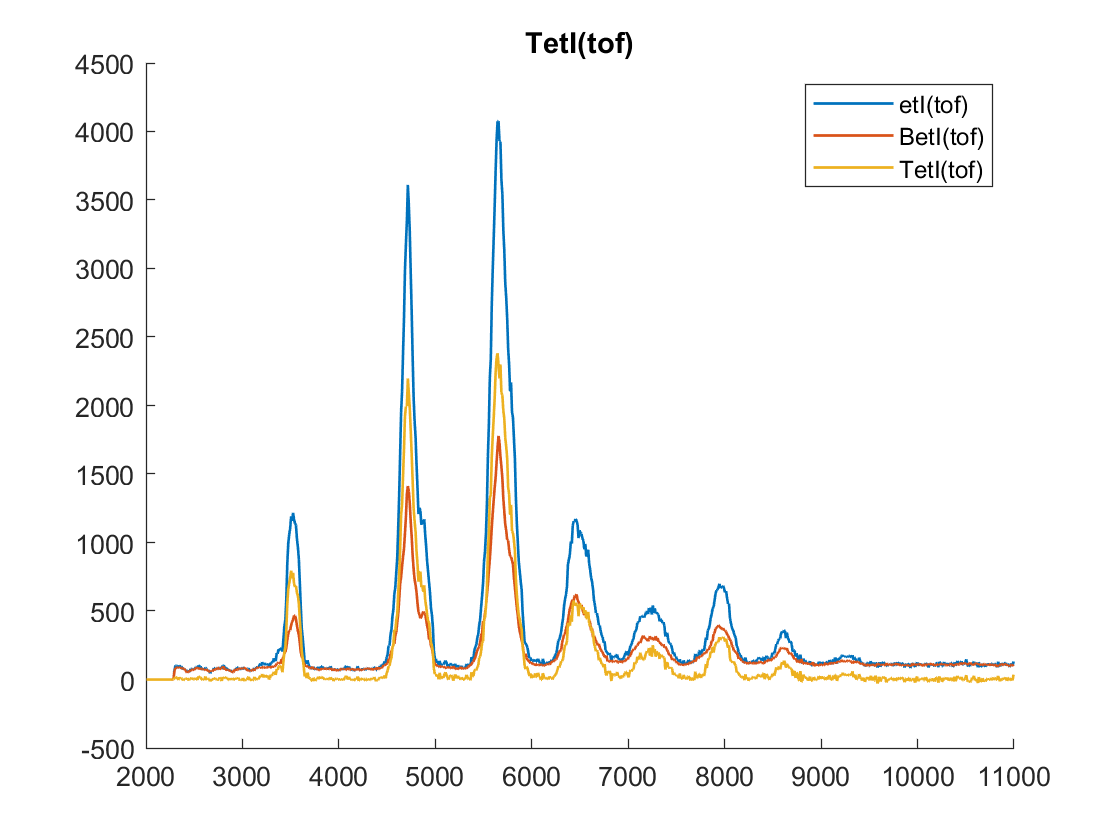

Bet_tof1 = SC.* TP_0 .*rt_tof1;
Tet_tof1 = et_tof1 - Bet_tof1;
figure
hold on
plot(Bincenters, et_tof1,'LineWidth',1,'DisplayName','etI(tof)'); 
plot(Bincenters, Bet_tof1,'LineWidth',1,'DisplayName','BetI(tof)'); 
plot(Bincenters, Tet_tof1,'LineWidth',1,'DisplayName','TetI(tof)'); 
title('TetI(tof)')
legend

% ylim([-100 2500])

## Calculate the Background BetII(tof1,tof2)

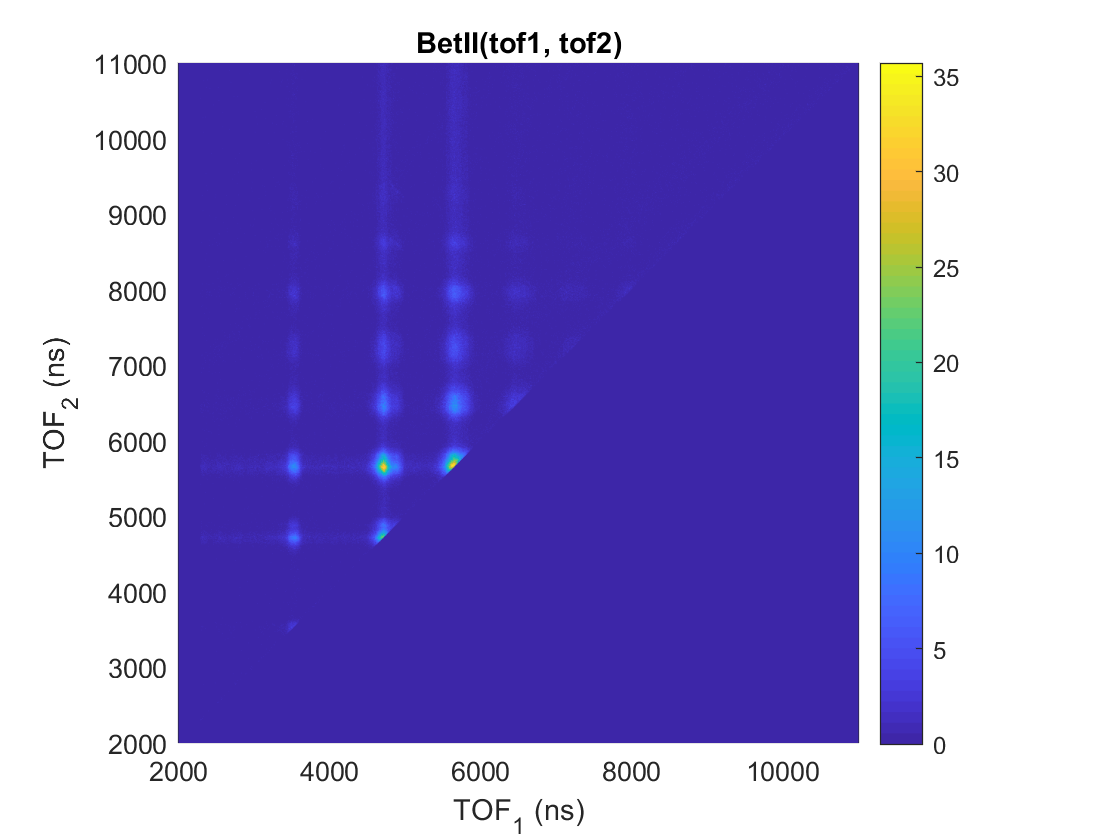

Bet_tof2= zeros(length(Bincenters));
for ii= 1:length(Bincenters)
    for jj = 1:length(Bincenters)
        if Bincenters(ii) < Bincenters (jj)
            a = (et_tof1(ii)*rt_tof1(jj) + et_tof1(jj)*rt_tof1(ii))/(data_stats.rtP_0*data_stats.N_RND);
            b = (2* SC * TP_0 *rt_tof1(ii)*rt_tof1(jj))/(data_stats.rtP_0*data_stats.N_RND);
            Bet_tof2(ii,jj) = SC .* TP_0.* rt_tof2(ii,jj) + a - b;
        else 
            Bet_tof2(ii,jj) = 0;
        end
    end
end
Bet_tof2=max(Bet_tof2,0);
figure
histogram2('XBinEdges',Binedges,'YBinEdges',Binedges,'BinCounts',Bet_tof2,'DisplayStyle','tile','ShowEmptyBins','on')
colorbar
title('BetII(tof1, tof2)')
xlabel('TOF_1 (ns)')
ylabel('TOF_2 (ns)')
axis equal

% caxis([0 10])

## Final filter True 2D map

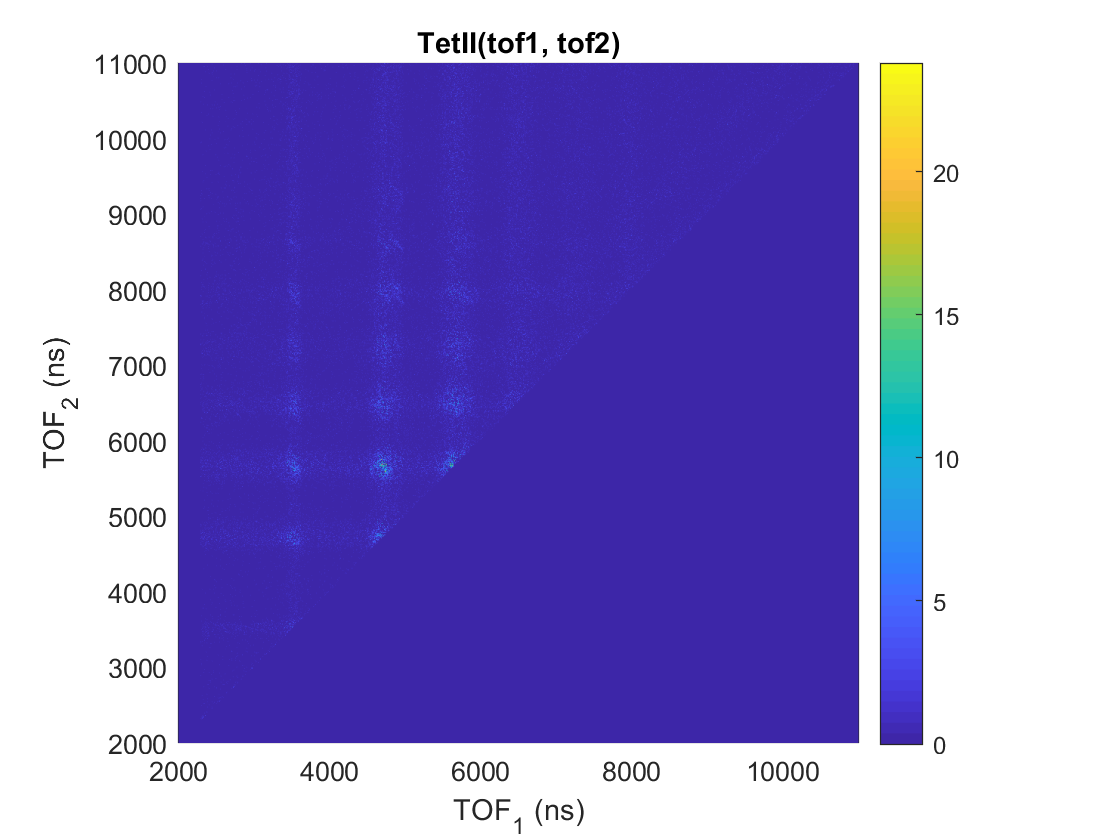

Tet_tof2 = et_tof2 - Bet_tof2;
Tet_tof2 = max(Tet_tof2,0);
figure
histogram2('XBinEdges',Binedges,'YBinEdges',Binedges,'BinCounts',Tet_tof2,'DisplayStyle','tile','ShowEmptyBins','on')
colorbar
title('TetII(tof1, tof2)')
xlabel('TOF_1 (ns)')
ylabel('TOF_2 (ns)')
axis equal


% xlim([4006 9670])
% ylim([4888 10553])
% caxis([0 4])
% xlim([4388 6221])
% ylim([7543 9376])

## Projections : Ion TOF for C2 

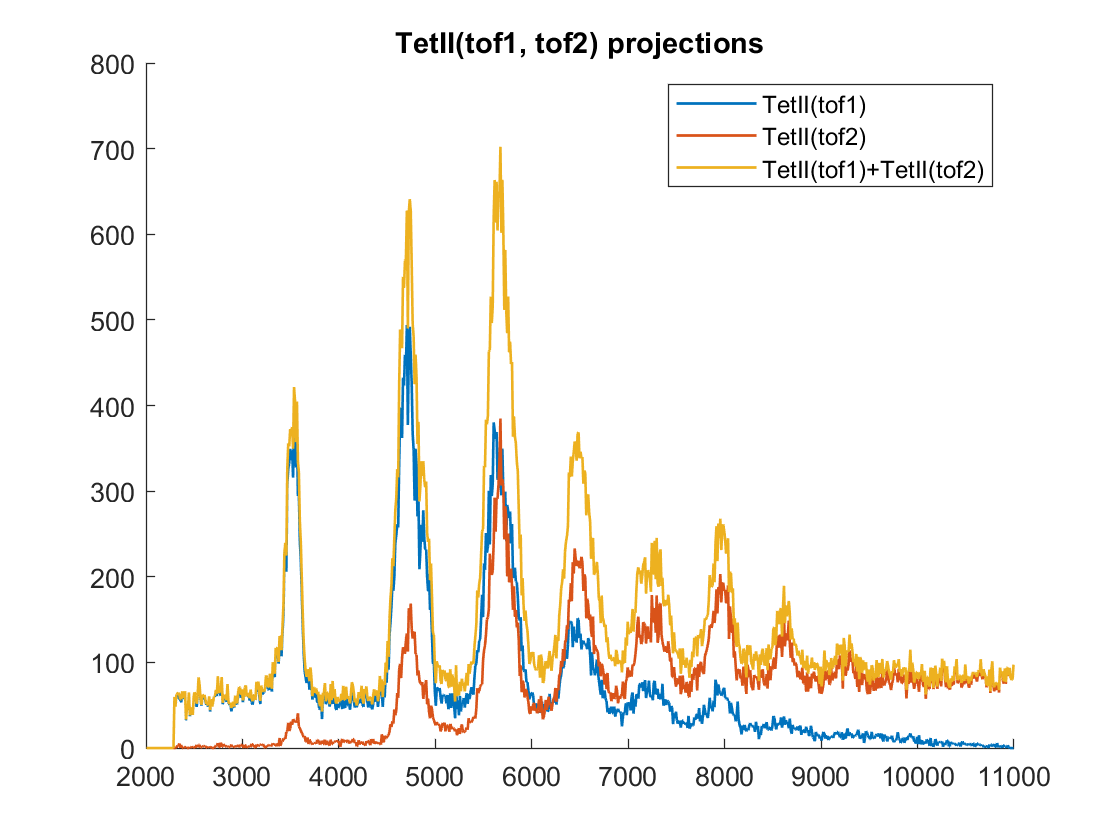

tof1_hist = sum(Tet_tof2,2);
tof2_hist = sum(Tet_tof2,1);

figure
hold on
plot(Bincenters, tof1_hist,'LineWidth',1,'DisplayName','TetII(tof1)');
plot(Bincenters, tof2_hist,'LineWidth',1,'DisplayName','TetII(tof2)');
title('TetII(tof1, tof2) projections')
legend

proj_Tet_tof2 = tof1_hist +tof2_hist';

plot(Bincenters, proj_Tet_tof2,'LineWidth',1,'DisplayName','TetII(tof1)+TetII(tof2)');

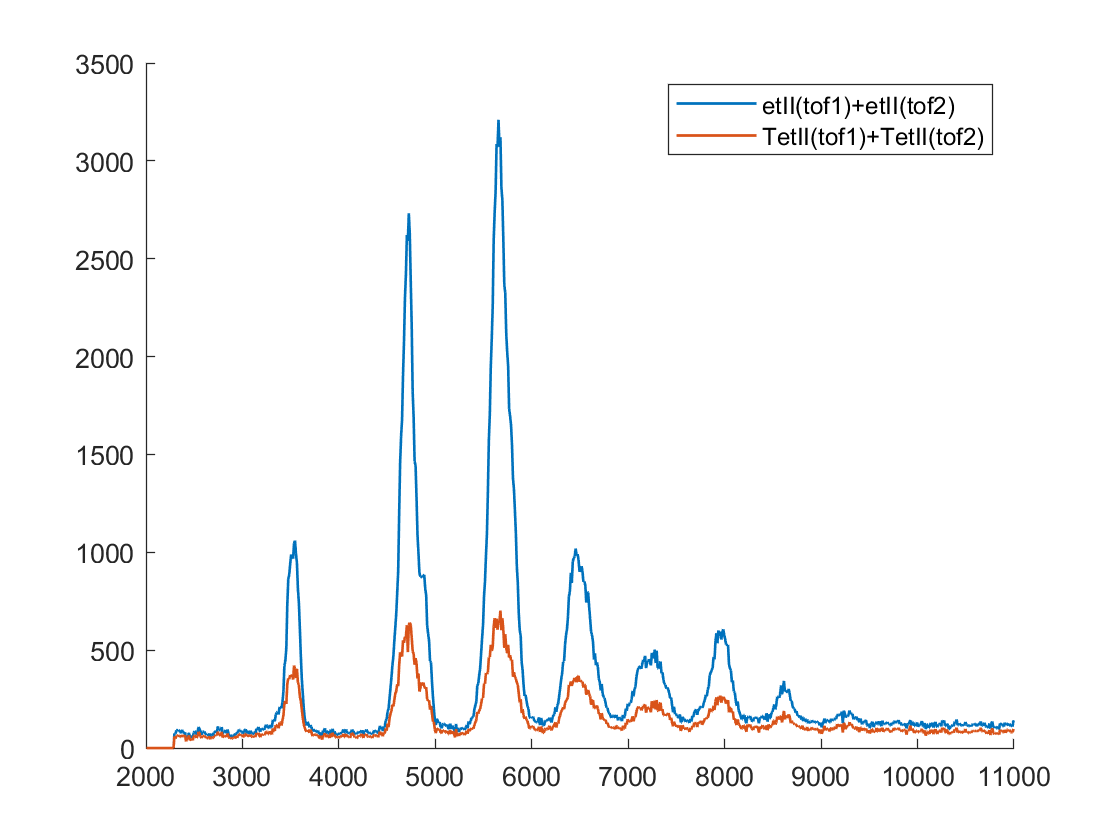

figure 
hold on
plot(Bincenters, proj_et_tof2,'LineWidth',1,'DisplayName','etII(tof1)+etII(tof2)');
plot(Bincenters, proj_Tet_tof2,'LineWidth',1,'DisplayName','TetII(tof1)+TetII(tof2)');
legend